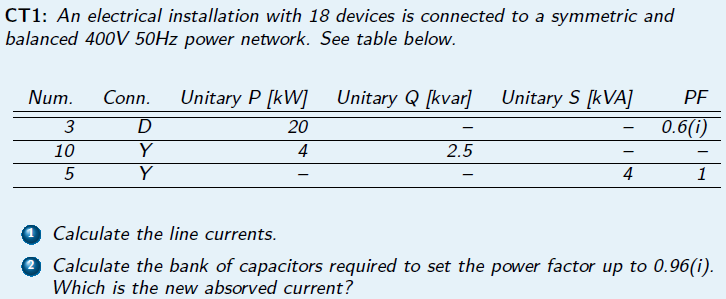

clear all
close all
clc

zab=20+20*1i

zab = 20.0000 + 20.0000i

zbc=20+20*1i

zbc = 20.0000 + 20.0000i

zca=20+20*1i

zca = 20.0000 + 20.0000i


U=400

U = 400


uan=U/sqrt(3)*exp(1i*0)

uan = 230.9401

ubn=U/sqrt(3)*exp(1i*-2*pi/3)

ubn = -1.1547e+02 - 2.0000e+02i

ucn=U/sqrt(3)*exp(1i*2*pi/3)

ucn = -1.1547e+02 + 2.0000e+02i


X=uan;disp(['uan=' num2str(abs(X)) ',' num2str(180/pi*angle(X)) 'V'])

uan=230.9401,0V


X=ubn;disp(['ubn=' num2str(abs(X)) ',' num2str(180/pi*angle(X)) 'V'])

ubn=230.9401,-120V


X=ucn;disp(['ucn=' num2str(abs(X)) ',' num2str(180/pi*angle(X)) 'V'])

ucn=230.9401,120V



uab=uan-ubn

uab = 3.4641e+02 + 2.0000e+02i

ubc=ubn-ucn

ubc = 0.0000e+00 - 4.0000e+02i

uca=ucn-uan

uca = -3.4641e+02 + 2.0000e+02i


X=uab;disp(['uab=' num2str(abs(X)) ',' num2str(180/pi*angle(X)) 'V'])

uab=400,30V


X=ubc;disp(['ubc=' num2str(abs(X)) ',' num2str(180/pi*angle(X)) 'V'])

ubc=400,-90V


X=uca;disp(['uca=' num2str(abs(X)) ',' num2str(180/pi*angle(X)) 'V'])

uca=400,150V


Càrregues 1

P=20000

P = 20000

cosfi=0.6

cosfi = 0.6000


Ia_1=P/(sqrt(3)*U*cosfi)

Ia_1 = 48.1125


I3a_1=3*Ia_1

I3a_1 = 144.3376



%angle carrega
phi=acos(0.6)*180/pi

phi = 53.1301

%angle corrent
I3_1ph=I3a_1*exp(1i*(-phi*pi/180))

I3_1ph = 8.6603e+01 - 1.1547e+02i


X=I3_1ph;disp(['I3_1ph=' num2str(abs(X)) ',' num2str(180/pi*angle(X)) 'A'])

I3_1ph=144.3376,-53.1301A


Càrregues 2

Pe=4000

Pe = 4000

Qe=2500

Qe = 2500

tanphi=Qe/Pe

tanphi = 0.6250

phi=atan(tanphi)*180/pi

phi = 32.0054

S=sqrt(Pe^2+Qe^2)

S = 4.7170e+03


Ia_2=S/(sqrt(3)*U)

Ia_2 = 6.8084


I10a_2=10*Ia_2

I10a_2 = 68.0839



%angle corrent
I10a_2ph=I10a_2*exp(1i*(-phi*pi/180))

I10a_2ph = 57.7350 - 36.0844i


X=I10a_2ph;disp(['I10a_2ph=' num2str(abs(X)) ',' num2str(180/pi*angle(X)) 'A'])

I10a_2ph=68.0839,-32.0054A


Càrregues 3


S=4000

S = 4000


Ia_3=S/(sqrt(3)*U)

Ia_3 = 5.7735


I5a_3=5*Ia_3

I5a_3 = 28.8675



%angle carrega
phi=acos(1)*180/pi

phi = 0

%angle corrent
I5_3ph=I5a_3*exp(1i*(-phi*pi/180))

I5_3ph = 28.8675


X=I5_3ph;disp(['I5_3ph=' num2str(abs(X)) ',' num2str(180/pi*angle(X)) 'A'])

I5_3ph=28.8675,0A




Ia_tot=I3_1ph+I10a_2ph+I5_3ph

Ia_tot = 1.7321e+02 - 1.5155e+02i


X=Ia_tot;disp(['Ia_tot=' num2str(abs(X)) ',' num2str(180/pi*angle(X)) 'A'])

Ia_tot=230.1494,-41.1859A


Compensem fins a cosphi=0.96(i)

Pt=3*20000+10*4000+5*4000

Pt = 120000

Qt=3*20000*tan((acos(0.6)))+10*2500+0

Qt = 1.0500e+05


Qdesitjada=Pt*tan(acos(0.96))

Qdesitjada = 3.5000e+04

Qbank=Qdesitjada-Qt

Qbank = -70000


% Noves corrents

Snew=sqrt(Pt^2+Qdesitjada^2)

Snew = 125000

I=Snew/(sqrt(3)*U)

I = 180.4220